%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clc; clear all; close all;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Data
A = [-2,0;0,-1]; % dx = A*x

% Bidimensional non- Linear System
syms x y

fx = x*(3-x-2*y)

$$fx = -x\,\left(x+2\,y-3\right)$$

fy = y*(2-x-y)

$$fy = -y\,\left(x+y-2\right)$$


fixPts = solve([fx;fy], [x;y]);
fixPts = double([fixPts.x'; fixPts.y'])

fixPts =      0     3     0     1
     0     0     2     1


%Calculate the jacaobian
Jac = jacobian([fx,fy])

$$Jac = \left(\begin{array}{cc} 3-2\,y-2\,x & -2\,x\\ -y & 2-2\,y-x \end{array}\right)$$


JacFixPts = zeros(2,2,size(fixPts, 2));

for k=1:size(fixPts,2);
    JacFixPts(:,:,k) = double(subs(Jac,{x,y}, {fixPts(1,k), fixPts(2,k)}));
    disp(JacFixPts(:,:,k))
    %Compute eigenvalues
    disp("For each jacobian matrix we will get the eigenvectors and the eigenvalues")
    
    [eigVecJ,eigValJ] = eig(JacFixPts(:,:,k))
    disp(eigVecJ)
end

     3     0
     0     2



For each jacobian matrix we will get the eigenvectors and the eigenvalues


eigVecJ =      0     1
     1     0


eigValJ =      2     0
     0     3


     0     1
     1     0



    -3    -6
     0    -1



For each jacobian matrix we will get the eigenvectors and the eigenvalues


eigVecJ =     1.0000   -0.9487
         0    0.3162


eigValJ =     -3     0
     0    -1


    1.0000   -0.9487
         0    0.3162



    -1     0
    -2    -2



For each jacobian matrix we will get the eigenvectors and the eigenvalues


eigVecJ =          0    0.4472
    1.0000   -0.8944


eigValJ =     -2     0
     0    -1


         0    0.4472
    1.0000   -0.8944



    -1    -2
    -1    -1



For each jacobian matrix we will get the eigenvectors and the eigenvalues


eigVecJ =     0.8165    0.8165
   -0.5774    0.5774


eigValJ =     0.4142         0
         0   -2.4142


    0.8165    0.8165
   -0.5774    0.5774




h1 = figure; hold on; grid on
plot(fixPts(1,:), fixPts(2,:), "o", "MarkerFaceColor", "r")


%Nullclines

%x-nullcline, solving for x and y, sometimes gets different results
%Esta parte va a intentar probar con a depejar en x e y, idealmente
%obtendremos la misma recta pero a veces no funciona así

xcline_x = solve(fx, x), x_cline_y = solve(fx, y)

$$xcline\_x = \left(\begin{array}{c} 0\\ 3-2\,y \end{array}\right)$$

$$x\_cline\_y = \frac{3}{2}-\frac{x}{2}$$

ycline_x = solve(fy, x), ycline_y = solve(fy, y)

$$ycline\_x = 2-y$$

$$ycline\_y = \left(\begin{array}{c} 0\\ 2-x \end{array}\right)$$


figure(h1);

fimplicit(fx, [-eps 3.5 -eps 2.5], "r--", "LineWidth",1.5)
fimplicit(fy, [-eps 3.5, -eps 2.5], "g--", "LineWidth",1.5);
axis([-eps 3.5 -eps 2.5]);


%General flow
N = 10;  %size of the grid
xlin = linspace(0,3.5, N); ylin = linspace(0,2.5, N)

ylin =          0    0.2778    0.5556    0.8333    1.1111    1.3889    1.6667    1.9444    2.2222    2.5000


[X_grid, Y_grid] = meshgrid(xlin, ylin);
Xgrid_v = X_grid(:); Ygrid_v = Y_grid(:);
x_Flowgrid = double(subs(fx, {x,y}, {Xgrid_v, Ygrid_v}))

x_Flowgrid =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


y_Flowgrid = double(subs(fy, {x,y}, {Xgrid_v, Ygrid_v}))

y_Flowgrid =          0
    0.4784
    0.8025
    0.9722
    0.9877
    0.8488
    0.5556
    0.1080
   -0.4938
   -1.2500



plot(Xgrid_v, Ygrid_v, "r.")

%Normal quiver

quiver(Xgrid_v, Ygrid_v, x_Flowgrid, y_Flowgrid)
%Normalize quiver
vecFlow_n = [x_Flowgrid';y_Flowgrid']

vecFlow_n =          0         0         0         0         0         0         0         0         0         0    1.0154    0.7994    0.5833    0.3673    0.1512   -0.0648   -0.2809   -0.4969   -0.7130   -0.9290    1.7284    1.2963    0.8642    0.4321         0   -0.4321   -0.8642   -1.2963   -1.7284   -2.1605    2.1389    1.4907    0.8426    0.1944   -0.4537   -1.1019   -1.7500   -2.3981   -3.0463   -3.6944    2.2469    1.3827    0.5185   -0.3457   -1.2099   -2.0741   -2.9383   -3.8025   -4.6667   -5.5309
         0    0.4784    0.8025    0.9722    0.9877    0.8488    0.5556    0.1080   -0.4938   -1.2500         0    0.3704    0.5864    0.6481    0.5556    0.3086   -0.0926   -0.6481   -1.3580   -2.2222         0    0.2623    0.3704    0.3241    0.1235   -0.2315   -0.7407   -1.4043   -2.2222   -3.1944         0    0.1543    0.1543         0   -0.3086   -0.7716   -1.3889   -2.1605   -3.0864   -4.1667         0    0.0463   -0.0617   -0.3241   -0.7407   -1.3117   -2.0370   -2.9167   -3.9

vecFlow_n = vecFlow_n ./ vecnorm(vecFlow_n);
vecFlow_n(1,:)

ans =        NaN         0         0         0         0         0         0         0         0         0    1.0000    0.9073    0.7052    0.4930    0.2627   -0.2055   -0.9497   -0.6084   -0.4648   -0.3857    1.0000    0.9801    0.9191    0.8000         0   -0.8815   -0.7593   -0.6783   -0.6139   -0.5602    1.0000    0.9947    0.9836    1.0000   -0.8268   -0.8191   -0.7833   -0.7430   -0.7025   -0.6634    1.0000    0.9994    0.9930   -0.7295   -0.8529   -0.8452   -0.8218   -0.7935   -0.7632   -0.7326


vecFlow_n(2,:)

ans =        NaN    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000   -1.0000   -1.0000         0    0.4204    0.7090    0.8700    0.9649    0.9787   -0.3131   -0.7936   -0.8854   -0.9226         0    0.1984    0.3939    0.6000    1.0000   -0.4722   -0.6508   -0.7348   -0.7894   -0.8283         0    0.1030    0.1802         0   -0.5625   -0.5736   -0.6217   -0.6693   -0.7117   -0.7482         0    0.0335   -0.1182   -0.6839   -0.5222   -0.5345   -0.5697   -0.6086   -0.6461   -0.6807


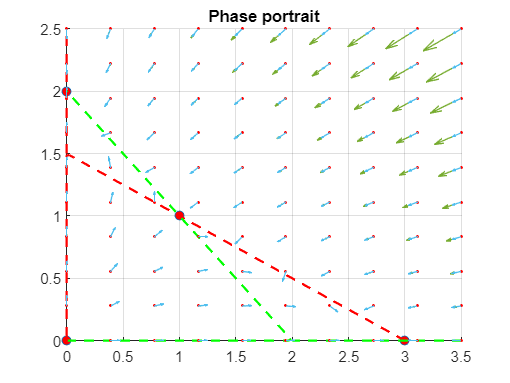

quiver(Xgrid_v, Ygrid_v, vecFlow_n(1,:)', vecFlow_n(2,:)',0.2)
title("Phase portrait")


% Plot trajectory

